% Comandos para la PowerShell:
  % cd C:\Users\usuario\Desktop\Renate-files\files
  % Dir|%{Rename-Item $_ -NewName ("Renate_{0}.txt" -f $nr++)}

% Obtener el número de archivos de datos en la carpeta  
listFiles = dir('C:\Users\usuario\Desktop\Renate-files\files\*.txt');
numFiles = numel(listFiles);

% Extraer la información de cada archivo y ponerla toda junta

rawdata = [];

for i=1000:1292
    
    myfilename=['C:\Users\usuario\Desktop\Renate-files\files\Renate_',num2str(i),'.txt'];
    %rawdata = [rawdata; import2019(myfilename)]; para la primera parte de
    %2019
    rawdata = [rawdata; import2020(myfilename)];
    
end

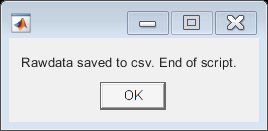


% Eliminar el sufijo -DRAIN de los nombres que lo tienen
rawdata.Type = erase(rawdata.Type,'-DRAIN');

% Eliminar las filas que corresponden a encabezado de tabla y órdenes d Go to sleep y
% Wake up
rawdata(rawdata.Type == 'Type', :) = [];
rawdata(rawdata.Type == 'GO TO SLEEP', :) = []; 
rawdata(rawdata.Type == 'WAKE UP', :) = [];
rawdata(rawdata.Type == 'SHUT DOWN', :) = [];

% Guardar los datos en un csv
ask1 = "Rawdata table created. Generate csv file? y/n ";
answer1 = input(ask1, "s");

if answer1 == "y"
    ask2 = "Name of file? (date): ";
    csvName = "C:\Users\usuario\Desktop\Renate-files\" + input(ask2, "s") + ".csv";
    writetable(rawdata, csvName, "Delimiter", "\t");
    msgbox("Rawdata saved to csv. End of script.");
else
    msgbox("Rawdata not saved to csv. End of script.");
end

CO2errors = [512, 32768, 33280, 35328, 49664, 34816, 34304, 33792];
errorRows = find(rawdata.error == CO2errors);
A0 = rawdata;

for k = 1:numel(A0.error)
    if ismember(A0.error(k), CO2errors) && isnan(A0.TSGSalt(k)) && A0.equPress(k) > 35
        A0(k, 37:end) = A0(k, 24:29);
        A0(k, 24:29) = {NaN, NaN, NaN, NaN, NaN, NaN};
        A0(k, "CO2Umm") = {NaN};

    elseif A0.error(k) == 512 && isnan(A0.TSGSalt(k)) && A0.H2OFlow(k) > 35
        A0(k, 37:end) = A0(k, 25:30);
        A0(k, 25:30) = {NaN, NaN, NaN, NaN, NaN, NaN};
        A0(k, "CO2Umm") = {NaN};
    end
end

% Crear la variable de trabajo a partir de los datos en bruto
A = A0(:, ["Type", "error", "PCDate", "PCTime", "stdVal", "CO2Umm", "latitude", "longitude", "H2OFlow", "licorFlow", "equTemp", "licorTemp", "IntakeTemp", "TSGTemp", "Temp", "licorPress", "atmPress", "equPress", "Oxygen", "TSGSalt"]);

% Añadir la variable de fecha y quitar las variables de GPSDate y gpsTime

A.PCDate.Format = "dd/MM/uuuu HH:mm:ss";
A.PCTime.Format = "dd/MM/uuuu HH:mm:ss";
A.Date = A.PCDate + timeofday(A.PCTime);
A.JulianDate = exceltime(A.Date);

A.PCDate = [];
A.PCTime = [];

% Hallar filas que dieron NaN y eliminarlas
% noTime = find(isnan(A.JulianDate(A.Type ~= "STD2")));
% A(noTime, :) = [];
nonDate = find(isnan(A.JulianDate));
A(nonDate, :) = [];

% Añadir las variables de presión en atm y quitar las variables en bares
A.licorPress2 = A.licorPress * 0.000986923;
A.atmPress2 = A.atmPress * 0.000986923;
A.equPress2 = A.equPress * 0.000986923;

A.licorPress = [];
A.atmPress = [];
A.equPress = [];

% Hacer NaN los valores de TEMP y SAL que son 0
disp(numel(A.TSGTemp(A.TSGTemp == 0)) + " TSG temperature values in " + numel(A.TSGTemp) + " values are 0.");

2325 TSG temperature values in 125322 values are 0.


disp(numel(A.TSGSalt(A.TSGSalt == 0)) + " salinity temperature values in " + numel(A.TSGSalt) + " values are 0.");

2325 salinity temperature values in 125322 values are 0.



A.TSGTemp = standardizeMissing(A.TSGTemp, 0);
A.TSGSalt = standardizeMissing(A.TSGSalt, 0);

disp(numel(find(isnan(A.TSGTemp))) + " TSG temperature values are now NaN.");

10884 TSG temperature values are now NaN.


disp(numel(find(isnan(A.TSGSalt))) + " salinity values are now NaN.");

10884 salinity values are now NaN.



% Encontrar valores nulos de temperatura
nullInt = find(isnan(A.IntakeTemp));
nullTSG = find(isnan(A.TSGTemp));
nullEqu = find(isnan(A.equTemp));

disp(numel(nullInt) + " Intake temperature values are NaN.");

11029 Intake temperature values are NaN.


disp(numel(nullTSG) + " TSG temperature values are NaN.");

10884 TSG temperature values are NaN.


disp(numel(nullEqu) + " Equ temperature values are NaN.");

0 Equ temperature values are NaN.



% Encontrar valores erróneos de temperatura
badInt = find(A.IntakeTemp > 30 | A.IntakeTemp < 14);
badTSG = find(A.TSGTemp > 35 | A.TSGTemp < 14);
badEqu = find(A.equTemp > 35 | A.equTemp < 14);

disp("There are " + numel(badInt) + " wrong Intake Temperature values in " + numel(A.IntakeTemp) + " values.");

There are 189 wrong Intake Temperature values in 125322 values.


disp("There are " + numel(badTSG) + " wrong TSG Temperature values in " + numel(A.TSGTemp) + " values.");

There are 5 wrong TSG Temperature values in 125322 values.


disp("There are " + numel(badEqu) + " wrong Equ Temperature values in " + numel(A.equTemp) + " values.");

There are 1566 wrong Equ Temperature values in 125322 values.



% Convertir en NaN los valores erróneos de temperatura
A.IntakeTemp = standardizeMissing(A.IntakeTemp, A.IntakeTemp(badInt));
A.TSGTemp = standardizeMissing(A.TSGTemp, A.TSGTemp(badTSG));
A.equTemp = standardizeMissing(A.equTemp, A.equTemp(badEqu));

disp(numel(find(isnan(A.IntakeTemp))) + " Intake temperature values are now NaN.");

11218 Intake temperature values are now NaN.


disp(numel(find(isnan(A.TSGTemp))) + " TSG temperature values are now NaN.");

10889 TSG temperature values are now NaN.


disp(numel(find(isnan(A.equTemp))) + " Equ temperature values are now NaN.");

1566 Equ temperature values are now NaN.



% Añadir las variables de diferencia de temperatura 
A.DiffEquInt = A.equTemp - A.IntakeTemp;
A.DiffTSGint = A.TSGTemp - A.IntakeTemp;
A.DiffEquTSG = A.equTemp - A.TSGTemp;

% Hallar diferencias de temperatura mayores de 2 grados y menores de cero,
% así como valores NaN
badDiffEquInt= find(abs(A.DiffEquInt) > 2 | A.DiffEquInt < 0);
badDiffEquInt2 = find(abs(A.DiffEquInt) > 1.5 | A.DiffEquInt < 0);
nullDiffEquInt = find(isnan(A.DiffEquInt));

disp(numel(nullDiffEquInt) + " difference values are NaN.");

12482 difference values are NaN.


disp("There are " + numel(badDiffEquInt) + " bad difference values (some of them are > 2) in " + numel(A.DiffEquInt) + " values.");

There are 6243 bad difference values (some of them are > 2) in 125322 values.


disp("There are " + numel(badDiffEquInt2) + " bad difference values (some of them are > 1.5) in " + numel(A.DiffEquInt) + " values.");

There are 6961 bad difference values (some of them are > 1.5) in 125322 values.



% Convertir en NaN estos valores de diferencia de temperatura
A.DiffEquInt = standardizeMissing(A.DiffEquInt, A.DiffEquInt([badDiffEquInt; badDiffEquInt2]));
allNullDiffEquInt = find(isnan(A.DiffEquInt));
CO2nullDiffEquInt = find(A.Type == "EQU" & isnan(A.DiffEquInt));
disp(numel(find(allNullDiffEquInt)) + " Equ-Int difference values are now NaN.");

19443 Equ-Int difference values are now NaN.


disp(numel(CO2nullDiffEquInt) + " Equ-Int difference values for Equ CO2 are NaN.");

17251 Equ-Int difference values for Equ CO2 are NaN.



% Encontrar valores erróneos de salinidad y convertirlos en NaN. Hallar
% también valores NaN inicialmente
badSAL = find(A.TSGSalt < 34);
nullSAL = find(isnan(A.TSGSalt));
disp(numel(nullSAL) + " Salinity values are NaN.");

10884 Salinity values are NaN.


disp("There are " + numel(badSAL) + " wrong salinity values in " + numel(A.TSGSalt) + " values.");

There are 3188 wrong salinity values in 125322 values.


A.TSGSalt = standardizeMissing(A.TSGSalt, A.TSGSalt(badSAL));
disp(numel(find(isnan(A.TSGSalt))) + " salinity values are now NaN.");

14072 salinity values are now NaN.



% Encontrar valores erróneos de presión atmosférica y convertirlos en NaN.
% Hallar también valores NaN iniciales
badPress = find(A.atmPress2 < 0.9);
nullPress = find(isnan(A.atmPress2));
disp(numel(nullPress) + " atm pressure values are NaN.");

27775 atm pressure values are NaN.


disp("There are " + numel(badPress) + " wrong pressure values in " + numel(A.atmPress2) + " values.");

There are 8821 wrong pressure values in 125322 values.


A.atmPress2 = standardizeMissing(A.atmPress2, A.atmPress2(badPress));
disp(numel(find(isnan(A.atmPress2))) + " pressure values are now NaN.");

36596 pressure values are now NaN.



% Encontrar valores erróneos de flujo de agua en el equilibrador y convertirlos en NaN.
% Hallar también valores NaN iniciales
badH2O = find(A.H2OFlow < 2.5);
nullH2O = find(isnan(A.H2OFlow));
disp(numel(nullH2O) + " H2O flow values are NaN.");

31706 H2O flow values are NaN.


disp("There are " + numel(badH2O) + " wrong H2O flow values in " + numel(A.H2OFlow) + " values.");

There are 27846 wrong H2O flow values in 125322 values.


%A.H2OFlow = standardizeMissing(A.H2OFlow, A.H2OFlow(badH2O));
allNullH2O = find(isnan(A.H2OFlow));
disp(numel(allNullH2O) + " H2O flow values are now NaN.");

31706 H2O flow values are now NaN.


CO2nullH2O = find(A.Type == "EQU" & isnan(A.H2OFlow));
disp(numel(CO2nullH2O) + " H2O flow values for Equ CO2 are NaN.");

28698 H2O flow values for Equ CO2 are NaN.



% Encontrar valores erróneos de CO2 y convertirlos en NaN. Eliminar también
% valores para los que la temperatura y el flujo de agua son erróneos
badCO2 = find(A.Type == "EQU" & (A.CO2Umm > 500 | A.CO2Umm < 360));
disp("There are " + numel(badCO2) + " bad CO2 values in " + numel(A.CO2Umm) + " values.");

There are 14997 bad CO2 values in 125322 values.


disp("There are " + numel(find(isnan(A.CO2Umm))) + " NaN CO2 values in " + numel(A.CO2Umm) + " values.");

There are 27943 NaN CO2 values in 125322 values.



%A.CO2Umm(sort([CO2nullDiffEquInt;CO2nullH2O;badCO2])) = NaN; 
disp(numel(find(isnan(A.CO2Umm))) + " CO2 values in " + numel(A.CO2Umm) + " are now NaN.");

27943 CO2 values in 125322 are now NaN.


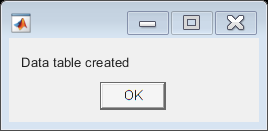


% Recolocar las columnas en la tabla
A = movevars(A, ["DiffEquInt" "DiffTSGint", "DiffEquTSG"], "After", "Temp");
A = movevars(A, ["Date", "JulianDate"], "After", "Type");

% Ordenar las filas por fecha
A = sortrows(A, "Date");

msgbox("Data table created");

A.CO2Umm = standardizeMissing(A.CO2Umm, A.CO2Umm(find(A.Type == "STD1" & A.CO2Umm > 5)));
A.CO2Umm = standardizeMissing(A.CO2Umm, A.CO2Umm(find(A.Type == "STD2" & A.CO2Umm > 300)));
A.CO2Umm = standardizeMissing(A.CO2Umm, A.CO2Umm(find(A.Type == "STD3" & A.CO2Umm > 500)));
A.CO2Umm = standardizeMissing(A.CO2Umm, A.CO2Umm(find(A.Type == "STD3" & A.CO2Umm < 300)));
A.CO2Umm = standardizeMissing(A.CO2Umm, A.CO2Umm(find(A.Type == "STD4" & A.CO2Umm > 560)));

A.CO2Umm = standardizeMissing(A.CO2Umm, A.CO2Umm(find(A.Type ~= "STD1" & A.CO2Umm < 40)));
A.CO2Umm = standardizeMissing(A.CO2Umm, A.CO2Umm(find(A.CO2Umm == 0)));

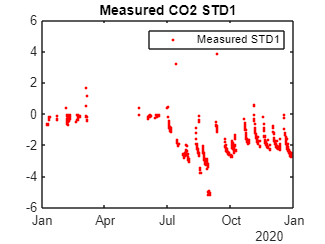

% Representar los valores medidos de los gases con su valor estándar

plot(A.Date(A.Type == "STD1"), A.CO2Umm(A.Type == "STD1"), ".r") % Gas 2
title("Measured CO2 STD1")
legend("Measured STD1", "Location", "northeast")

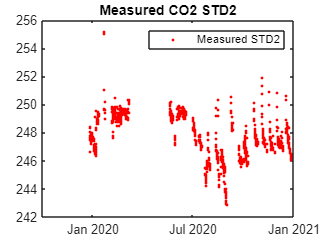


plot(A.Date(A.Type == "STD2"), A.CO2Umm(A.Type == "STD2"), ".r") % Gas 2
title("Measured CO2 STD2")
legend("Measured STD2", "Location", "northeast")

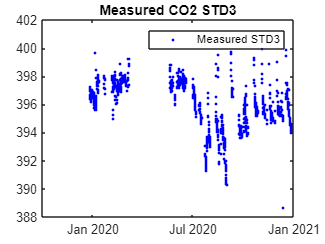


plot(A.Date(A.Type == "STD3"), A.CO2Umm(A.Type == "STD3"), ".b") % Gas 3
title("Measured CO2 STD3")
legend("Measured STD3", "Location", "northeast")

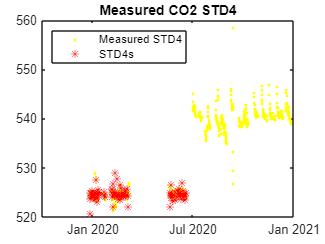


plot(A.Date(A.Type == "STD4"), A.CO2Umm(A.Type == "STD4"), ".y") % Gas 4
hold on
plot(A.Date(A.Type == "STD4s"), A.CO2Umm(A.Type == "STD4s"), "*r")
hold off
title("Measured CO2 STD4")
legend("Measured STD4", "STD4s", "Location", "northwest")

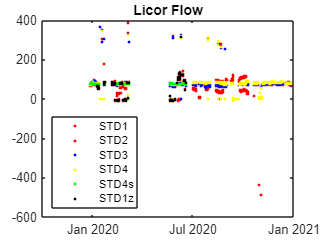



% Representar licor flow de los gases y de las mediciones atmosféricas y
% equilibrador
plot(A.Date(A.Type == "STD1"), A.licorFlow(A.Type == "STD1"), ".r") 
hold on
plot(A.Date(A.Type == "STD2"), A.licorFlow(A.Type == "STD2"), ".r") 
hold on
plot(A.Date(A.Type == "STD3"), A.licorFlow(A.Type == "STD3"), ".b")
hold on
plot(A.Date(A.Type == "STD4"), A.licorFlow(A.Type == "STD4"), ".y")
hold on
plot(A.Date(A.Type == "STD4s"), A.licorFlow(A.Type == "STD4s"), ".g")
hold on
plot(A.Date(A.Type == "STD1z"), A.licorFlow(A.Type == "STD1z"), ".k")
hold off
title("Licor Flow")
legend("STD1", "STD2", "STD3", "STD4", "STD4s", "STD1z", "Location", "southwest")

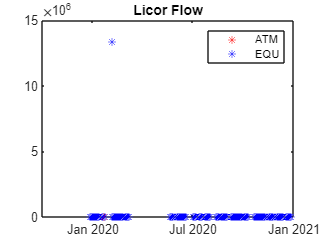


plot(A.Date(A.Type == "ATM"), A.licorFlow(A.Type == "ATM"), "*r")
hold on
plot(A.Date(A.Type == "EQU"), A.licorFlow(A.Type == "EQU"), "*b")
hold off
title("Licor Flow")
legend("ATM", "EQU")

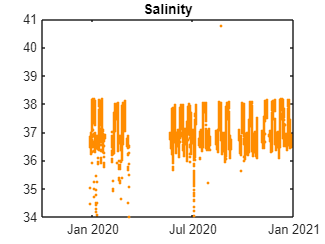

    

% Salinidad
plot(A.Date, A.TSGSalt, ".", "Color", "#FF8C00")
title("Salinity")

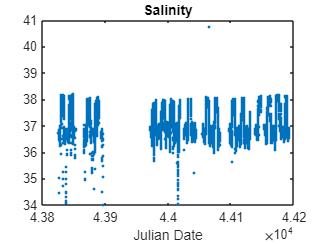

%ylim([35 39])

plot(A.JulianDate, A.TSGSalt, ".")
title("Salinity")
xlabel("Julian Date")

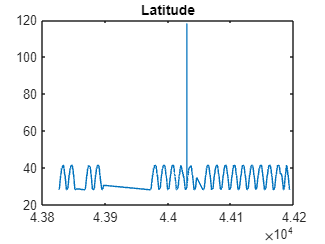

%ylim([35 39])


% Coordenadas
plot(A.JulianDate, A.latitude)
title("Latitude")

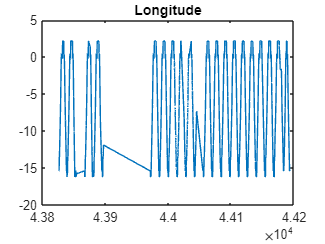


plot(A.JulianDate, A.longitude)
title("Longitude")

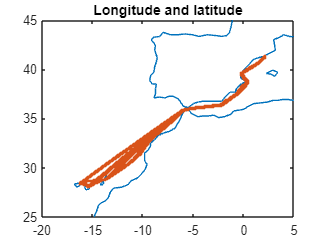


% Obtener las coordenadas máximas y mínimas medidas para comprobar si hay algún error
coord = table(min(A.longitude), min(A.latitude), max(A.longitude), max(A.latitude), 'VariableNames', {'minLon', 'minLat', 'maxLon', 'maxLat'});

load coastlines
plot(coastlon, coastlat)
hold on 
plot(A.longitude, A.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

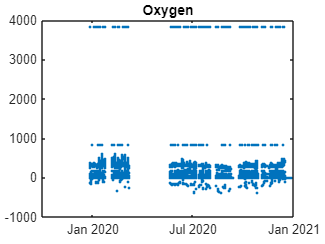



% Oxígeno
plot(A.Date, A.Oxygen, ".")
title("Oxygen")

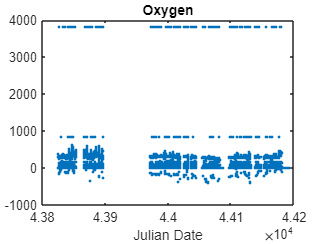

%ylim([200 350])

plot(A.JulianDate, A.Oxygen, ".")
title("Oxygen")
xlabel("Julian Date")

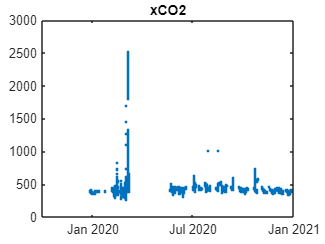

%ylim([200 350])


% xCO2 en el equilibrador
plot(A.Date(A.Type == "EQU"), A.CO2Umm(A.Type == "EQU"), ".")
title("xCO2")

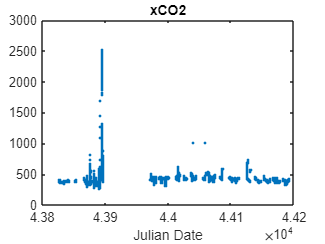

% ylim([350 550])

plot(A.JulianDate(A.Type == "EQU"), A.CO2Umm(A.Type == "EQU"), ".")
title("xCO2")
xlabel("Julian Date")

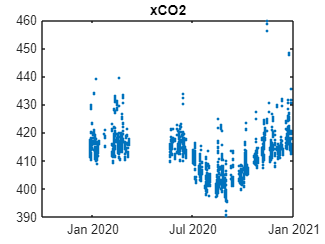

% ylim([350 550])


% xCO2 atmosférico
plot(A.Date(A.Type == "ATM"), A.CO2Umm(A.Type == "ATM"), ".")
title("xCO2")

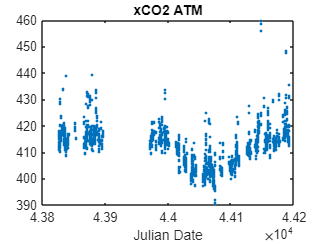

% ylim([350 550])

plot(A.JulianDate(A.Type == "ATM"), A.CO2Umm(A.Type == "ATM"), ".")
title("xCO2 ATM")
xlabel("Julian Date")

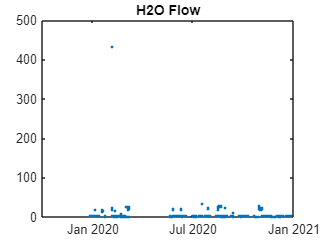

% ylim([350 550])


% Flujo de agua en el equilibrador
plot(A.Date(A.Type == "EQU"), A.H2OFlow(A.Type == "EQU"), ".")
% ylim([-0.5, 3.5])
title("H2O Flow")

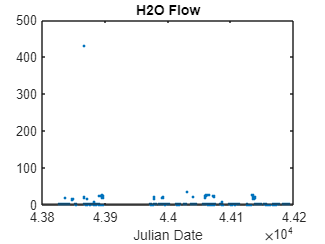

%ylim([0, 3.8])

plot(A.JulianDate(A.Type == "EQU"), A.H2OFlow(A.Type == "EQU"), ".")
hold on
yline(2.5)
hold off
% ylim([-0.5, 3.5])
title("H2O Flow")
xlabel("Julian Date")

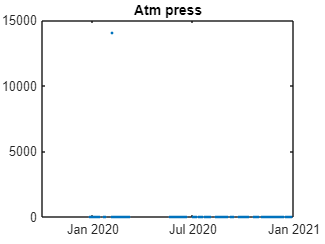



% Presiones

% Atm press
plot(A.Date, A.atmPress2, ".")
title("Atm press")

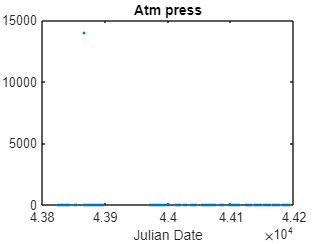

%ylim([0.97 1.03])

plot(A.JulianDate, A.atmPress2, ".")
title("Atm press")
xlabel("Julian Date")

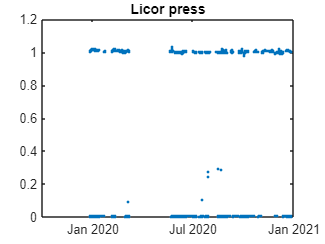

%ylim([0.97 1.03])

% Licor Press
plot(A.Date, A.licorPress2, ".")
title("Licor press")

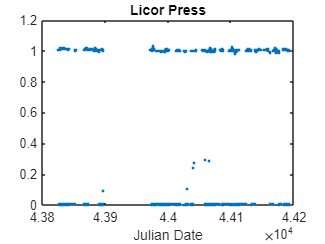


plot(A.JulianDate, A.licorPress2, ".")
title("Licor Press")
xlabel("Julian Date")

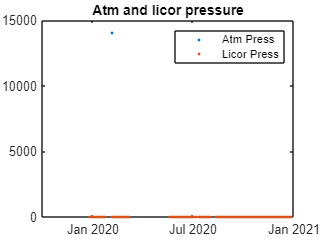


% Juntas
plot(A.Date, A.atmPress2, ".")
hold on
plot(A.Date, A.licorPress2, ".")
hold off
title("Atm and licor pressure")
legend("Atm Press", "Licor Press")

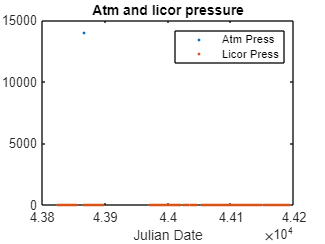

%ylim([0.97 1.03])

plot(A.JulianDate, A.atmPress2, ".")
hold on
plot(A.JulianDate, A.licorPress2, ".")
hold off
title("Atm and licor pressure")
legend("Atm Press", "Licor Press")
xlabel("Julian Date")

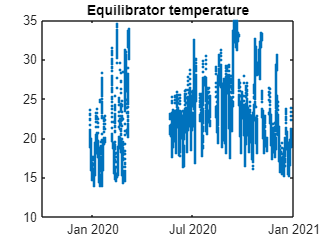

%ylim([0.97 1.03])


% Temperaturas

% Equ Temp
plot(A.Date, A.equTemp, ".")
title("Equilibrator temperature")

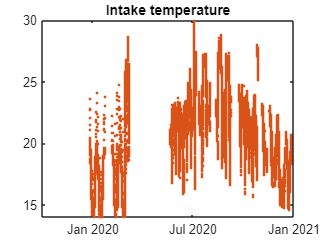

%ylim([14 32])

% Intake temp
plot(A.Date, A.IntakeTemp, ".", "Color", "#D95319")
title("Intake temperature")

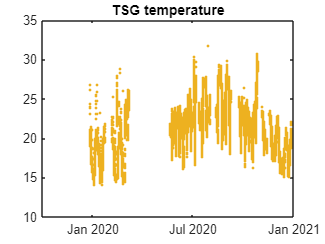

%ylim([11 24])
% A veces da valores de miles que habría que quitar

% TSG temp
plot(A.Date, A.TSGTemp, ".", "Color", 	"#EDB120")
title("TSG temperature")

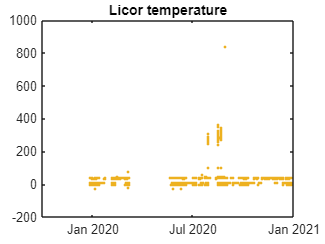

%ylim([14 30])
% A veces da valores de miles que habría que quitar 

% Licor temp
plot(A.Date, A.licorTemp, ".", "Color", "#EDB120")
title("Licor temperature")

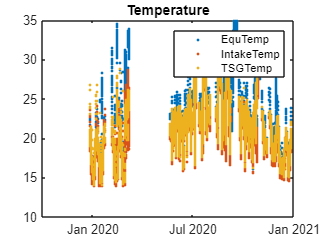

% ylim([14 30])

% Todas juntas menos licor temp
plot(A.Date, A.equTemp, ".")
hold on
plot(A.Date, A.IntakeTemp, ".")
hold on
plot(A.Date, A.TSGTemp, ".")
hold off
title("Temperature")
legend("EquTemp", "IntakeTemp", "TSGTemp")

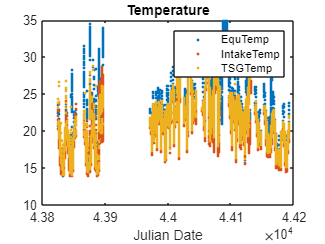

% ylim([15 24])
%ylim([12 32])

plot(A.JulianDate, A.equTemp, ".")
hold on
plot(A.JulianDate, A.IntakeTemp, ".")
hold on
plot(A.JulianDate, A.TSGTemp, ".")
hold off
title("Temperature")
legend("EquTemp", "IntakeTemp", "TSGTemp")
% ylim([15 30])
xlabel("Julian Date")

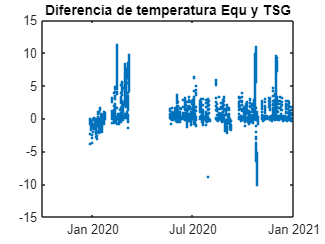

%ylim([12 32])


% Diferencias de temperatura

% Equ y TSG
plot(A.Date, A.DiffEquTSG, ".")
title("Diferencia de temperatura Equ y TSG")

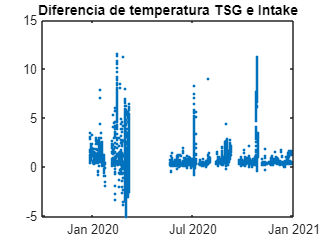

%ylim([-0.5 2.5])

% TSG e Intake
plot(A.Date, A.DiffTSGint, ".")
title("Diferencia de temperatura TSG e Intake")

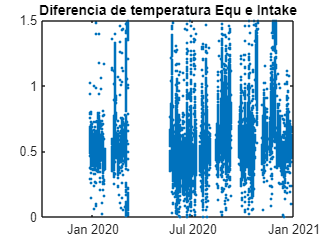

%ylim([0 2])

% Equ e Intake
plot(A.Date, A.DiffEquInt, ".")
title("Diferencia de temperatura Equ e Intake")
%ylim([0 2])
hold on
yline(1.5)
hold off

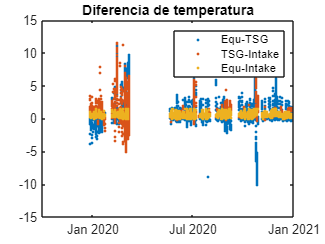


% Juntas 
plot(A.Date, A.DiffEquTSG, ".")
hold on
plot(A.Date, A.DiffTSGint, ".")
hold on
plot(A.Date, A.DiffEquInt, ".")
hold off
title("Diferencia de temperatura")
legend("Equ-TSG", "TSG-Intake", "Equ-Intake")

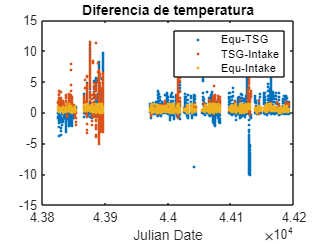

%ylim([-0.5 2])

plot(A.JulianDate, A.DiffEquTSG, ".")
hold on
plot(A.JulianDate, A.DiffTSGint, ".")
hold on
plot(A.JulianDate, A.DiffEquInt, ".")
hold off
title("Diferencia de temperatura")
legend("Equ-TSG", "TSG-Intake", "Equ-Intake")
xlabel("Julian Date")

%ylim([-0.5 2])

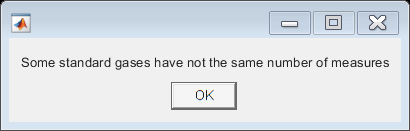

STD1Rows = find(A.Type == "STD1");
STD2Rows = find(A.Type == "STD2");
STD3Rows = find(A.Type == "STD3");
STD4Rows = find(A.Type == "STD4");
STD4sRows = find(A.Type == "STD4s");
STD1zRows = find(A.Type == "STD1z");
EQUrows = find(A.Type == "EQU");
STDsRows = find(A.Type == "STD1"| A.Type == "STD2" | A.Type == "STD3" | A.Type == "STD4" | A.Type == "STD4s" | A.Type == "STD1z");

% Indicar si los estándares presentan el mismo número de medidas (filas)
if any([size(STD1Rows) ~= size(STD2Rows), size(STD1Rows) ~= size(STD3Rows), size(STD1Rows) ~= size(STD4Rows), size(STD2Rows) ~= size(STD3Rows), size(STD2Rows) ~= size(STD4Rows), size(STD3Rows) ~= size(STD4Rows)])
   msgbox("Some standard gases have not the same number of measures");
else 
   msgbox("Same number of measures for all standard gases");
end

A1 = A(1:6961, :);
A2 = A(6981:end, :);

% A1 
STD1column = A1.CO2Umm;
STD2column = A1.CO2Umm;
STD3column = A1.CO2Umm;
STD4column = A1.CO2Umm;

nonSTD1 = find(A1.Type ~= "STD1");
nonSTD2 = find(A1.Type ~= "STD2");
nonSTD3 = find(A1.Type ~= "STD4");
nonSTD4 = find(A1.Type ~= "STD4");

% Hacer NaN en los valores que no corresponden a cada estándar
STD1column(nonSTD1) = NaN;
STD2column(nonSTD2) = NaN;
STD3column(nonSTD3) = NaN;
STD4column(nonSTD4) = NaN;

for m=1:(numel(STD3column)-1)
    if ~isnan(STD3column(m)) && ~isnan(STD3column(m+1))
        STD3column(m+1) = NaN;
    end
end

for m=1:(numel(STD4column)-1)
    if ~isnan(STD4column(m)) && ~isnan(STD4column(m+1))
        STD3column(m) = NaN;
    end
end

julianDate = A1{:, "JulianDate"};
STDtable = table(STD1column, STD2column, STD3column, STD4column, julianDate);

interpol = fillmissing(STDtable(:, 1:4), 'linear', 'SamplePoints', STDtable.julianDate);
A1 = [A1, interpol];

Data = A1(:, ["Type", "JulianDate", "Date", "CO2Umm", "latitude", "longitude", "equTemp", "licorTemp", "licorPress2","atmPress2","equPress2","H2OFlow", "licorFlow","IntakeTemp", "TSGTemp", "TSGSalt", "STD1column", "STD2column", "STD3column", "STD4column"]);
writetable(Data, 'second2020.csv', 'Delimiter', '\t')

% A2 
STD1column = A2.CO2Umm;
STD2column = A2.CO2Umm;
STD3column = A2.CO2Umm;
STD4column = A2.CO2Umm;

nonSTD1 = find(A2.Type ~= "STD1");
nonSTD2 = find(A2.Type ~= "STD2");
nonSTD3 = find(A2.Type ~= "STD3");
nonSTD4 = find(A2.Type ~= "STD4");

% Hacer NaN en los valores que no corresponden a cada estándar
STD1column(nonSTD1) = NaN;
STD2column(nonSTD2) = NaN;
STD3column(nonSTD3) = NaN;
STD4column(nonSTD4) = NaN;

julianDate = A2{:, "JulianDate"};
STDtable = table(STD1column, STD2column, STD3column, STD4column, julianDate);

interpol = fillmissing(STDtable(:, 1:4), 'linear', 'SamplePoints', STDtable.julianDate);
A2 = [A2, interpol];

Data = A2(:, ["Type", "JulianDate", "Date", "CO2Umm", "latitude", "longitude", "equTemp", "licorTemp", "licorPress2","atmPress2","equPress2","H2OFlow", "licorFlow","IntakeTemp", "TSGTemp", "TSGSalt", "STD1column", "STD2column", "STD3column", "STD4column"]);
writetable(Data, 'second2020.csv', 'Delimiter', '\t')

% Representar valores corregidos
plot(A.Date(A.Type == "EQU"), A.xCO2corr(A.Type == "EQU"), ".")
title("Corrected xCO2")

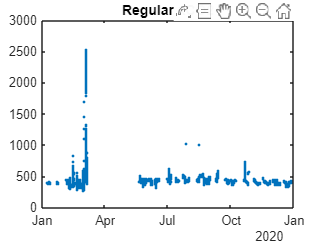


plot(A.Date(A.Type == "EQU"), A.CO2Umm(A.Type == "EQU"), ".")
title("Regular xCO2")

Af = A(A.latitude < 30 & A.latitude > 28.50 & A.longitude < -15.3 & A.longitude > -15.6 & A.Type == "EQU", :);

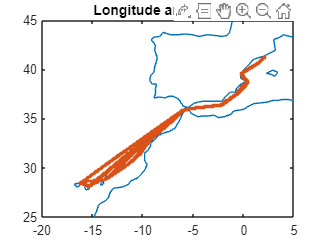

load coastlines
plot(coastlon, coastlat)
hold on 
plot(A.longitude, A.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

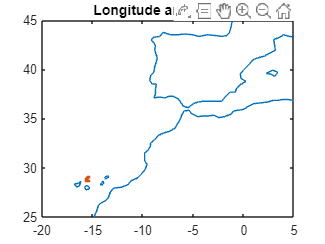

plot(coastlon, coastlat)
hold on 
plot(Af.longitude, Af.latitude, ".")
hold off
title("Longitude and latitude")
xlim([-20 5])
ylim([25 45])

data = Af(:, ["Date","JulianDate","latitude","longitude","CO2Umm", "pCO2sw","fCO2sw", "IntakeTemp", "SAL"]);

writetable(data, 'ESTOC2020.csv', 'Delimiter', '\t')